#### Задача 3.9.

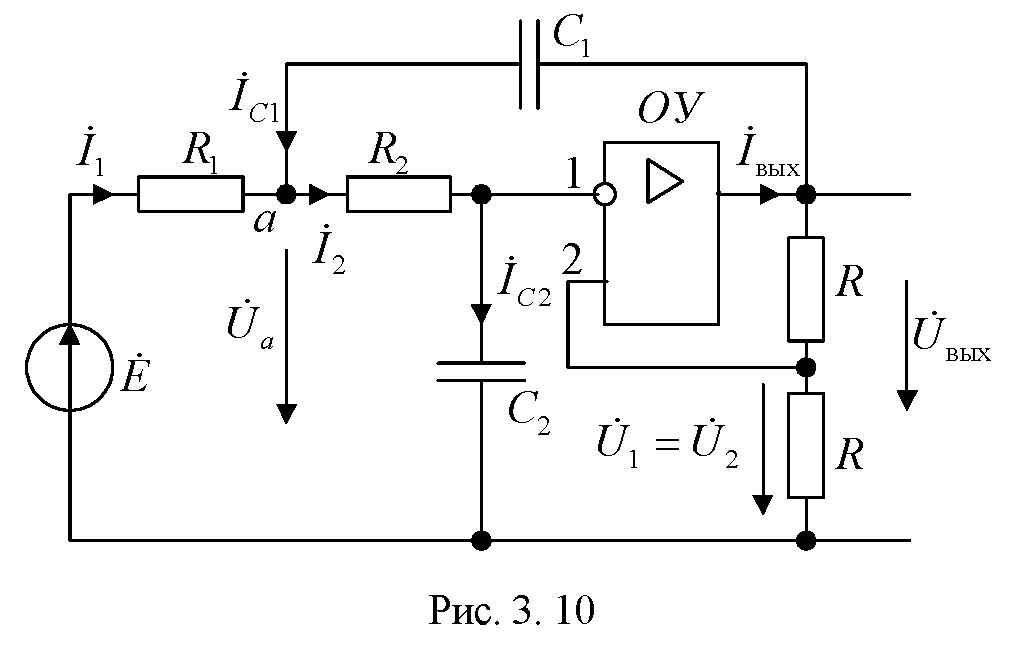

clear
format short
digits(3)
E=1; % В
f=1000; % Гц
R1=2300; % Ом
R2=R1;
R=5100; % Ом
C1=0.068; % мкФ
C2=C1;

syms I1 I2 I_C1 I_C2 U1 U2 U_out U_a 
syms R1 R2 Z_C1 Z_C2 E
I2==I_C2

$$ans = I_{2}=I_{\mathrm{C2}}$$

U1==U2, U1==U_out/2

$$ans = U_{1}=U_{2}$$

$$ans = U_{1}=\frac{U_{\mathrm{out}}}{2}$$

Уравнения первого закона Кирхгофа для узлов а и 1 имеют вид:

eq1=-I1+I2-I_C1==0,...
eq2=-I2+I_C2==0

$$eq1 = I_{2}-I_{1}-I_{\mathrm{C1}}=0$$

$$eq2 = I_{\mathrm{C2}}-I_{2}=0$$

eq1=subs(eq1,[I1 I2 I_C1 I_C2],...
    [(E-U_a)/R1, (U_a-U_out/2)/R2, (U_out-U_a)/Z_C1, U_out/(2*Z_C2)]),...
eq2=subs(eq2,[I1 I2 I_C1 I_C2],...
    [(E-U_a)/R1, (U_a-U_out/2)/R2, (U_out-U_a)/Z_C1, U_out/(2*Z_C2)])

$$eq1 = \frac{U_{a}-\frac{U_{\mathrm{out}}}{2}}{R_{2}}-\frac{\text{E}-U_{a}}{R_{1}}+\frac{U_{a}-U_{\mathrm{out}}}{Z_{\mathrm{C1}}}=0$$

$$eq2 = \frac{U_{\mathrm{out}}}{2\,Z_{\mathrm{C2}}}-\frac{U_{a}-\frac{U_{\mathrm{out}}}{2}}{R_{2}}=0$$

Получаем узловые уравнения

eq1=collect(eq1,[U_a U_out]),...
eq2=collect(eq2,[U_a U_out])

$$eq1 = \left(\frac{1}{R_{1}}+\frac{1}{R_{2}}+\frac{1}{Z_{\mathrm{C1}}}\right)\,U_{a}+\left(-\frac{1}{2\,R_{2}}-\frac{1}{Z_{\mathrm{C1}}}\right)\,U_{\mathrm{out}}-\frac{\text{E}}{R_{1}}=0$$

$$eq2 = \left(-\frac{1}{R_{2}}\right)\,U_{a}+\left(\frac{1}{2\,R_{2}}+\frac{1}{2\,Z_{\mathrm{C2}}}\right)\,U_{\mathrm{out}}=0$$

E=1; % В
f=1000; % Гц
R1=2300; % Ом
R2=R1;
R=5100; % Ом
C1=0.068; % мкФ
C2=C1;

Расчет емкостных сопротивлений на частоте f

Z_C1=1/(1j*2*pi*f*C1*1e-6)

Z_C1 = 0.0000e+00 - 2.3405e+03i

Z_C2=1/(1j*2*pi*f*C2*1e-6)

Z_C2 = 0.0000e+00 - 2.3405e+03i

Расчет матрицы узловых проводимостей

Y11=1/R1+1/R2+1/Z_C1

Y11 = 8.6957e-04 + 4.2726e-04i

Y12=1/(2*R2)+1/Z_C1

Y12 = 2.1739e-04 + 4.2726e-04i

Y21=1/R2

Y21 = 4.3478e-04

Y22=1/(2*R2)+1/(2*Z_C2)

Y22 = 2.1739e-04 + 2.1363e-04i

J11=E/R1, J22=0

J11 = 4.3478e-04

J22 = 0

Ynn=[Y11 -Y12;...
    -Y21 Y22]

Ynn = 	1.0e+-3 *

   0.8696 + 0.4273i  -0.2174 - 0.4273i
  -0.4348 + 0.0000i   0.2174 + 0.2136i


Узловые токи

Jnn=[J11;J22]

Jnn = 	1.0e+-3 *

    0.4348
         0


Расчет узловых напряжений

Un0=Ynn^(-1)*Jnn

Un0 =    1.0343 - 0.9815i
   0.0710 - 2.0328i


U_a=vpa(Un0(1)), Up_a=vpa([abs(U_a),angle(U_a)*180/pi])

$$U\_a = 1.03-0.981\,\mathrm{i}$$

$$Up\_a = \left(\begin{array}{cc} 1.43 & -43.5 \end{array}\right)$$

Комплексное действующее значение выходного напряжения

U_out=vpa(Un0(2)), Up_out=vpa([abs(U_out),angle(U_out)*180/pi])

$$U\_out = 0.071-2.03\,\mathrm{i}$$

$$Up\_out = \left(\begin{array}{cc} 2.03 & -88.0 \end{array}\right)$$

Амплитудное значение

Um=vpa(Up_out(1)*sqrt(2))

$$Um = 2.88$$

Угол сдвига фаз

Psi=0-(Up_out(2))

$$Psi = 88.0$$